%% initialize environments
clc;
clear variables;

%% set AudioFileManipulator class parameters
input_file_path = "vaiueo2d.wav";

%% generate AudioFileManipulator instance and confirm properties
audio_file_manipulator = AudioFileManipulator(input_file_path);
audio_file_manipulator.load_properties();
audio_file_manipulator.display_properties();

--------------------------------------------
---------- Audio File Manipulator ----------
input_file_path : vaiueo2d.wav
output_file_path : default.wav
signal shape : (17500, 1)
sample_rate: 22050 [Hz]
             Filename: 'D:\名城大学\研究室\演習\MatlabPractice\SourceCode\Analysis\STRAIGHT\STRAIGHTV40_007b\vaiueo2d.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 22050
         TotalSamples: 17500
             Duration: 0.7937
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16

--------------------------------------------



%% set LinearPredictiveCoding class parameters
start_point = 3748;  % あのスタート位置
continue_time = 32; % [ms]
continue_point = int32(continue_time * audio_file_manipulator.information.SampleRate / 1000);

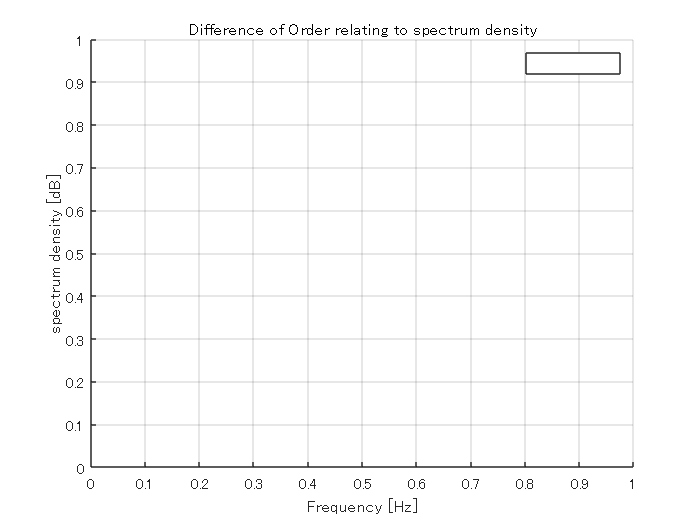

%% set figure parameters
hold on;
grid on;
title("Difference of Order relating to spectrum density");
xlabel("Frequency [Hz]");
ylabel("spectrum density [dB]");
legend;

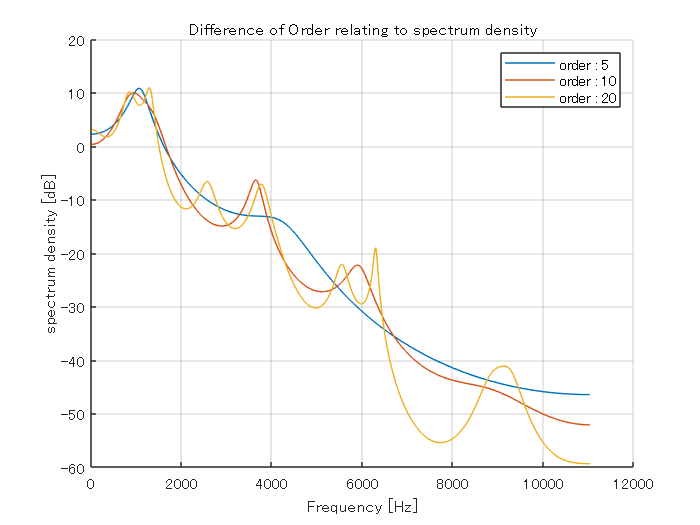

%% generate LinearPredictiveCoding instance and plot spectrum density
order_list = [5, 10, 20];
for order_index = 1 : length(order_list)
    lpc = LinearPredictiveCoding(audio_file_manipulator.signal(start_point : start_point + continue_point - 1), audio_file_manipulator.information.SampleRate, "hamming", order_list(order_index));
    plot((1 : length(lpc.spectrum_density)) / length(lpc.spectrum_density) * (audio_file_manipulator.information.SampleRate / 2), lpc.get_spectrum_density_dB(), "DisplayName", "order : " + int2str(order_list(order_index)));
end

%% save result
saveas(gcf, "D:/名城大学/研究室/演習/data/LPC/Difference_of_Order_relating_to_spectrum_density.png");

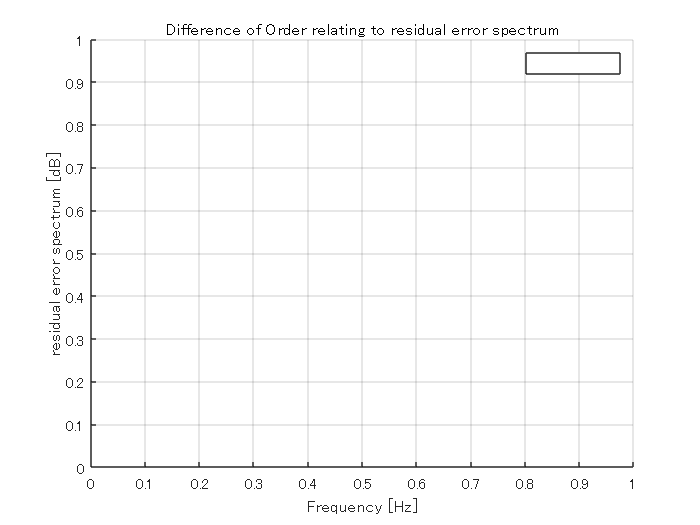

%% set figure parameters
delete(gcf);
hold on;
grid on;
title("Difference of Order relating to residual error spectrum");
xlabel("Frequency [Hz]");
ylabel("residual error spectrum [dB]");
legend;

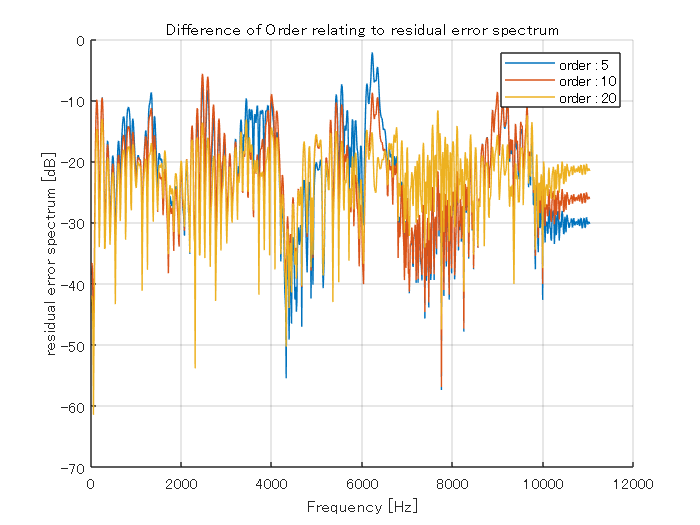

%% generate LinearPredictiveCoding instance and plot residual error
for order_index = 1 : length(order_list)
    lpc = LinearPredictiveCoding(audio_file_manipulator.signal(start_point : start_point + continue_point - 1), audio_file_manipulator.information.SampleRate, "hamming", order_list(order_index));
    plot((1 : length(lpc.get_residual_error_spectrum_dB())) / length(lpc.get_residual_error_spectrum_dB()) * audio_file_manipulator.information.SampleRate / 2, lpc.get_residual_error_spectrum_dB(), "DisplayName", "order : " + int2str(order_list(order_index)));
end

saveas(gcf, "D:/名城大学/研究室/演習/data/LPC/Difference_of_Order_relating_to_residual_error_spectrum.png");

delete(gcf);

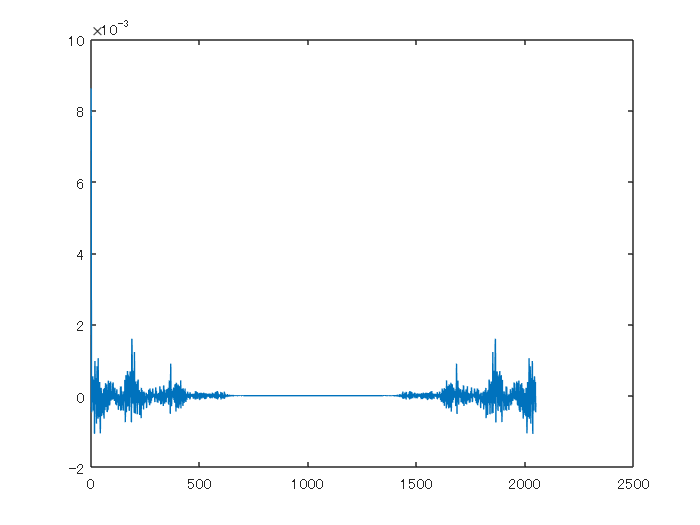

plot(lpc.modified_autocorrelation);